clear; close all; clc;tic;

Num_bits = 10^6;
Data = randn(1,Num_bits) > 0.5;
SNR=0:0.1:10;

Coded_Data = Hamming_7_4_Encoder(Data);
BPSK_Mod_Data = 2*Coded_Data-1;
coded_BER = zeros(1,length(SNR));

for i=1:length(SNR)
    fprintf("\b\b\b\b\b%%%d", i-1);
    AWGN_Data = awgn(complex(BPSK_Mod_Data),SNR(i),"measured");
    BPSK_Demod_Data = AWGN_Data > 0;
    Decoded_Data = Hamming_7_4_Decoder(BPSK_Demod_Data);
    coded_BER(i) = sum(Data~=Decoded_Data)/Num_bits;
end

%101

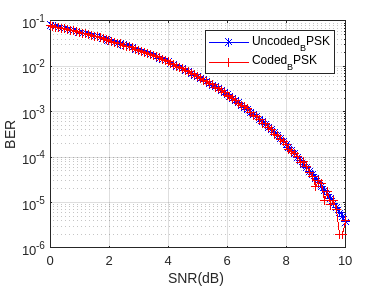

Done.

fprintf("\b\b\b\b\bResult:");
uncoded_BER = berawgn(SNR, "psk", 2, "nondiff");

semilogy(SNR, uncoded_BER, 'b*-','linewidth',1);grid on; hold on;
semilogy(SNR, coded_BER, 'r+-','linewidth',1); grid on;
xlabel('SNR(dB) '); ylabel('BER'); legend('Uncoded_BPSK','Coded_BPSK');

toc;

Elapsed time is 824.803123 seconds.
